clear, clc, close all;


syms("a", "b", "c", "d", "t");

func = a*t^3 + b*t^2 + c*t + d;

func_d = diff(func, t, 1)

$$func\_d = 3\,a\,t^{2}+2\,b\,t+c$$

func_dd = diff(func, t, 2)

$$func\_dd = 2\,b+6\,a\,t$$

equ1 = subs(func, "t", 0.5) == 0.5

$$equ1 = \frac{a}{8}+\frac{b}{4}+\frac{c}{2}+d=\frac{1}{2}$$

equ2 = subs(func_dd, "t", 0.5) == 0

$$equ2 = 3\,a+2\,b=0$$

A = [3, 2, 0, 0;
    1, 2, 4, 8]

A =      3     2     0     0
     1     2     4     8


B = [0;
    4]

B =      0
     4


sys_equs = A*[a; b; c; d] == B

$$sys\_equs = \left(\begin{array}{c} 3\,a+2\,b=0\\ a+2\,b+4\,c+8\,d=4 \end{array}\right)$$

syms("k1", "k2");

a = k1;
b = -3*k1/2;
c = k2;
d = 1/2+k1/4-k2/2;

params = [a; b; c; d];
func_sol = subs(func)

$$func\_sol = k_{1}\,t^{3}-\frac{3\,k_{1}\,t^{2}}{2}+k_{2}\,t+\frac{k_{1}}{4}-\frac{k_{2}}{2}+\frac{1}{2}$$

% eqution to solve
equ_to_solve = func_sol - 1/2 == 0

$$equ\_to\_solve = k_{1}\,t^{3}-\frac{3\,k_{1}\,t^{2}}{2}+k_{2}\,t+\frac{k_{1}}{4}-\frac{k_{2}}{2}=0$$

% discriminant
D = simplify(b^2*c^2 - 4*a*c^3 - 4*b^3*(d-1/2) - 27*a^2*(d-1/2)^2 + 18*a*b*c*(d-1/2))

$$D = \frac{k_{1}\,{\left(3\,k_{1}-4\,k_{2}\right)}^{3}}{16}$$

% discriminant condition
equn_dis = simplify(D < 0)

$$equn\_dis = k_{1}\,{\left(3\,k_{1}-4\,k_{2}\right)}^{3}<0$$

% case 1
equn_dis_1 = k1 < 0;
equn_dis_2 = (3*k1 - 4*k2) > 0;
sol = solve([equn_dis_1 equn_dis_2], [k1 k2],'ReturnConditions',true)

sol = struct with fields:
            k1: x
            k2: y
    parameters: [x    y]
    conditions: (4*y)/3 < x & x < 0


sol.k1

$$ans = x$$

sol.k2

$$ans = y$$

sol.conditions

$$ans = \frac{4\,y}{3}<x\wedge x<0$$

% case 2
equn_dis_1 = k1 > 0;
equn_dis_2 = (3*k1 - 4*k2) < 0;
sol = solve([equn_dis_1 equn_dis_2], [k1 k2],'ReturnConditions',true)

sol = struct with fields:
            k1: x
            k2: y
    parameters: [x    y]
    conditions: x < (4*y)/3 & 0 < x


sol.k1

$$ans = x$$

sol.k2

$$ans = y$$

sol.conditions

$$ans = x<\frac{4\,y}{3}\wedge 0<x$$

equn_1 = subs(func_sol, t, 0) == 0

$$equn\_1 = \frac{k_{1}}{4}-\frac{k_{2}}{2}+\frac{1}{2}=0$$

equn_2 = subs(func_sol, t, 1) - 1 == 0

$$equn\_2 = \frac{k_{2}}{2}-\frac{k_{1}}{4}-\frac{1}{2}=0$$

solve([equn_1 equn_2], [k1 k2])

ans = struct with fields:
    k1: -2
    k2: 0


k1 = -4;
k2 = k1/2 + 1;

func_sol_2 = subs(func_sol)

$$func\_sol\_2 = -4\,t^{3}+6\,t^{2}-t$$

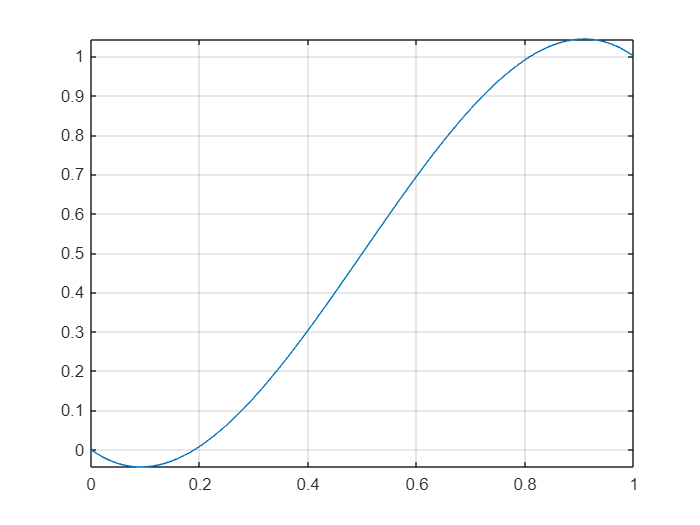

fplot(func_sol_2, [0 1])
grid on

solve(func_sol_2 == 1/2, t)

$$ans = \left(\begin{array}{c} \frac{1}{2}\\ \frac{1}{2}-\frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2}+\frac{1}{2} \end{array}\right)$$